**Analytical Case Study**

***by John D'Uva***

%% import data manually
data = AnalyticalCaseStudy2S1;
data.Properties.VariableNames{1} = 'Date';
data = removevars(data, {'VarName3','VarName7','VarName5'});

**Question 1**: **Calculate the productivity growth you would use to compensate employees for the most recent review period. Perform the calculation for each of the three employees, explain your calculation and why you chose the method you did. Keep in mind that this is for employee bonuses (not salaries).**

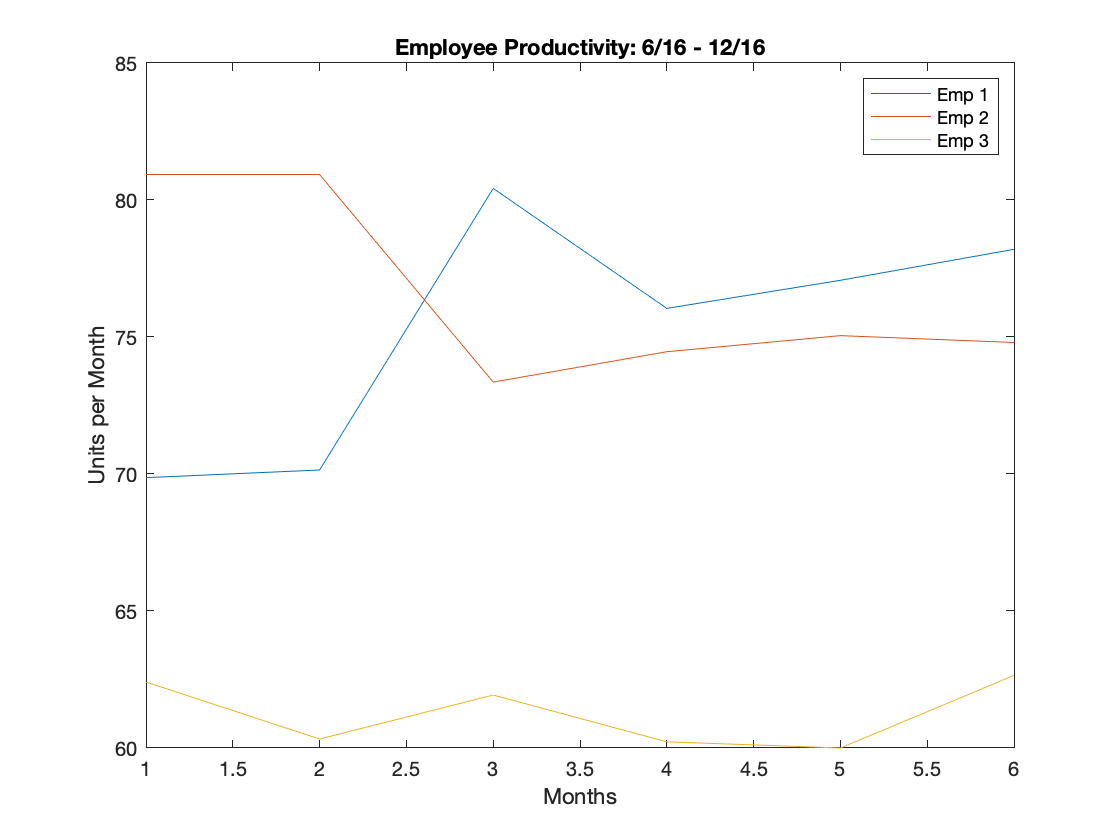

% take an initial look at the data 
eight = data{end-5:end, 2:4};
plot(eight)
xlabel('Months')
ylabel("Units per Month")
title("Employee Productivity: 6/16 - 12/16")
legend('Emp 1', 'Emp 2', 'Emp 3')

One way to calculate productivity growth is to compute the change in productivity divided by initial productivity: 

*r = (final - initial) / initial*

I chose this method because it allows for evaluating how each employee's productivity transitioned over time with respect to that particular employee's unique initial productivity level. This kind of system heavily rewards those who previously had lower productivity but have managed to improve during the 6 month period. The problem with this method is that it overlooks the productivity levels between the initial and end points, so an employee could exploit this by being very unproductive during months one through five and then exceptionally produtive during month 6. 

growth = (eight(end,:)-eight(1,:)) ./ eight(1,:);
for i = 1 : 3 
    disp( ['Employee ', num2str(i), ' growth rate = ', num2str(growth(i)*100), '%'] )
end

Employee 1 growth rate = 11.9273%
Employee 2 growth rate = -7.5756%
Employee 3 growth rate = 0.38922%


**Question 2:** **When looking at the percent change between review periods for each employee, is it important to use the average of 6-month productivity instead of the sum of 6-month productivity? Why or why not?**

seven = data{end-11:end-6, 2:4};
diff_sum = sum(seven(:,1)) / sum(eight(:,1));
diff_avg = mean(seven(:,1)) / mean(eight(:,1));
fprintf("Sum ratio = %.4f", diff_sum)

Sum ratio = 0.9574

fprintf("Avg ratio = %.4f", diff_avg)

Avg ratio = 0.9574

No, it is not important because the ratios of the sums are equivalent to the ratios of the averages.

**Question 3: Many candidates calculate growth by taking month over month changes for the most recent 6 months, and then taking the average of those growth numbers.  What are your thoughts on this approach?**

for i = 1 : 3
    fprintf("Employee %d: avg mo/mo = %f\n", i, mean(diff(eight(:,i))))
end

Employee 1: avg mo/mo = 1.666648
Employee 2: avg mo/mo = -1.226198
Employee 3: avg mo/mo = 0.048580


I think that this method could also be useful in some cases because instead of only considering the intial and final producitivity, it also incoprorates the intermediary productivity levels. However, this method suffers from a similar shortcoming in that it can be exploted by an employee who has very low productivity every other month. For example, if an employee's last six months of output were: **[70, 0, 71, 1, 69, 0, 71] **then his/her growth would be considered:

fprintf("Growth = %.2f%%", mean(diff([70 0 71 1 69 0 71]))*100 )

Growth = 16.67%

...which does not accurately reflect how productive the employee was. 

**Question 4: What if your business was an ice cream truck – what new types of things would you start to consider? How would you change your original calculation if needed? Make sure to explain your logic thoroughly.**

I would also consider how many hours that the employees are working and divide that by their production levels. This is important because perhaps one employee seems to be the most productive when in fact s/he is just working the  most hours and actually has lower productvity on a per-hour basis. One might also consider subtracting the amount of overhead for each employee. In the context of an ice cream truck, perhaps one employee's sales are very high but s/he has to drive two hours back and forth to a particular neighborhood in order to do so. This reduces the bottom line by increasing costs and should be taken into account. 

**Question 5: If all employees are given 4 weeks of vacation per year, does your original calculation correct for that or is there a bias present? In what cases would this be/not be an issue? How might you correct for such an issue if one exists?**

No, it does not correct for that and there would definitely be a bias present if those weeks of vacation are taken in either the first month or the sixth month. It would not be an issue if these vacations are taken during months 2 through 5 because those months are not considered in the original equation. There are a few ways that we could correct for such an issue, one of which is to generate an artifical measurement of productivity for the vacation weeks by interpolating from the prior and posterior weeks. For example, if a vacation was taken during [month 6, week 3], then we could use the productivity from week 2 and week 4 to generate an intermediary value so that our original equation holds. 

**Question 6: Is employee productivity growth in general a good way to evaluate employees when determining their bonuses? Why or why not? Make sure to explain your logic thoroughly.**

I do not think this is a good way to evaluate productivity because it punishes employees who have already reached their maximum productivity potential. These individuals can only improve their bonuses by actively reducing productivity in one period and excalating it again the next. This is not the kind of strategy that businesses want their employee's pursuing. While it has the benefit of motivating lower-producing individuals, it is still good practice to highly reward your best performers. Perhaps total productivity is a better metric to evaluate bonuses on rather than change in productivity over time. Indeed, this is what most companies seem to incorporate with motivators like cumulative sales and performance bonuses. 

**Question 7: What single piece of data would you most want to add to your assessment? Why? What other factors did you consider and why did you choose/not choose to include them?**

I am not sure how this question is different from Question 4 other than that this is asking for one specific component rather than multiple. If I am interpreting it correctly, the one piece of data that I would most want to add to my assessment is each employee's number of hours per productivty measurement (as I mentioned in my response to Question 4). This helps us determine how well employees are using the time that they are clocking and helps us evaluate which employees are the most/least efficient. Other factors that I considered are overhead costs per hour (which is important but won't move the bottom line as much as productivity per hour) and number of vacations taken (which is less important because these inidividuals may "cash out" their cumulative PTO instead of taking vacation). 

**Question 8: Imagine that a power failure occurs at your company, such that you lose all of the employee productivity data. How would you go about assessing your employees in a logical and systematic way? **

I would implement a kind of "Trust but Verify" honors system where I would ask employees to estimate (a) how productive they were this past month (b) how they rank among their peers, and (c) how their work ties in to the overall company operations (significant because those that can do their job well can usually explain what they do and how it ties into overall operations). I would then begin compiling more productivity data as we had done previously and assign bonuses for the previous period according to employee estimates as long as their future productivity lines up with these estimates. Also, I would find out why a power failure erased all of our productivity data and save new data on a more secure device.